
clear;

clockTimeLimit = 100; % 体験時間 (s)
period = 3; % 歩行周期 (s)

legForwardTimeRate = 3; % 足スライダ前進 時間比
legBackwardTimeRate = 4; % 足スライダ後退 時間比

stockForwardTimeRate = 3; % ストックスライダ前進 時間比
stockBackwardTimeRate = 4; % ストックスライダ後退 時間比

upTimeRate = 1; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 3; % ストック空中時間比
stockGroundTimeRate = 4; % ストック接地時間比

tiltBackwardTimeRate = stockForwardTimeRate;
tiltForwardTimeRate = stockBackwardTimeRate;

liftLength = 60; % 椅子 リフト長 単位 (mm)
pedalLength = 60; % ペダル長 単位 (mm)
seatSlideForwardLength = 50; % 椅子 スライド長 単位 (mm)
seatSlideBackwardLength = 100; % 椅子 スライド長 単位 (mm)
extendLength = 180; % 伸縮長 単位 (mm)
stockSlideForwardLength = 200; % ストック スライド前方向長 単位 (mm)
stockSlideBackwardLength = 200; % ストック スライド後方向長 単位 (mm)
tiltBackwardDeg = 0; % ストック 後傾角度 (deg)
tiltForwardDeg = -20; % ストック 前傾角度 (deg)

stockStartTime = -period/8;
waitTime = period/2;

椅子 リフト

L = liftLength; % スライド長 単位 (mm)
startClockTime = 0 + waitTime; % 開始時刻 (s)
if legForwardTimeRate < legBackwardTimeRate
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
else
    clockTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
    deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
end
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period/2:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period/2:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 133×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

        1.5       0.64286            60                0      
     2.1429       0.64286             0                0      
          3       0.64286            60                0      
     3.6429       0.64286             0                0      
        4.5       0.64286            60                0      
     5.1429       0.64286             0                0      
          6       0.64286            60                0      
     6.6429       0.64286             0                0      
        7.5       0.64286            60                0      
     8.1429       0.64286             0                0      
          9       0.64286            60                0      
     9.6429       0.64286             0                0      
       10.5       0.64286            60                0      
     11.143       0.64286        

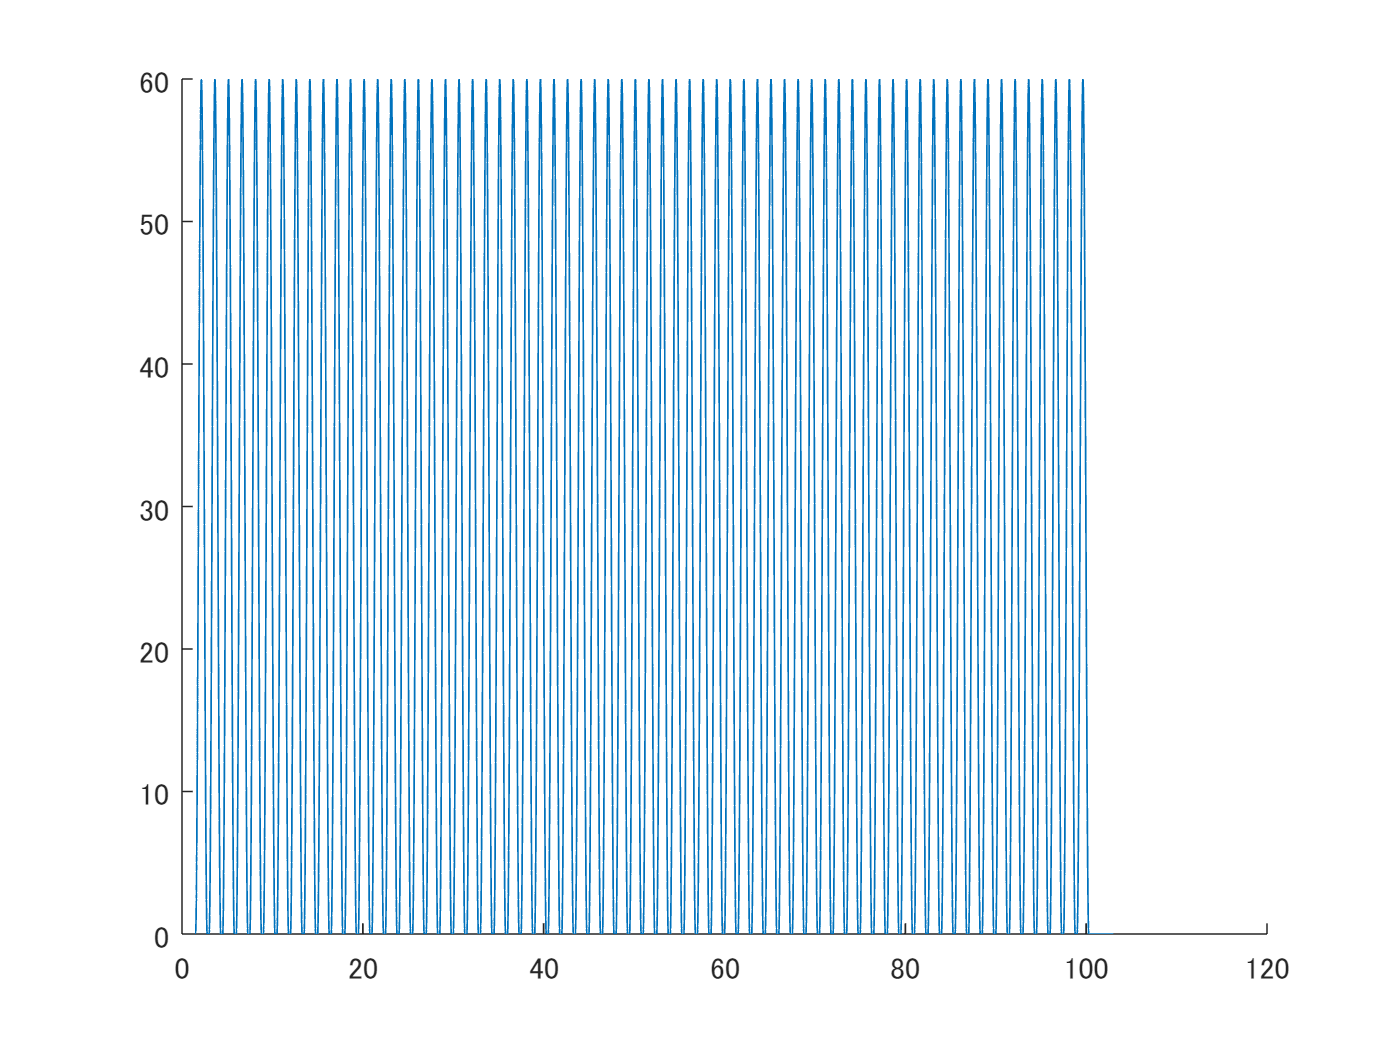

writetable(lifter, "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = waitTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

        1.5       0.64286            60                0      
     2.1429       0.64286             0                0      
        4.5       0.64286            60                0      
     5.1429       0.64286             0                0      
        7.5       0.64286            60                0      
     8.1429       0.64286             0                0      
       10.5       0.64286            60                0      
     11.143       0.64286             0                0      
       13.5       0.64286            60                0      
     14.143       0.64286             0                0      
       16.5       0.64286            60                0      
     17.143       0.64286             0                0      
       19.5       0.64286            60                0      
     20.143       0.64286      

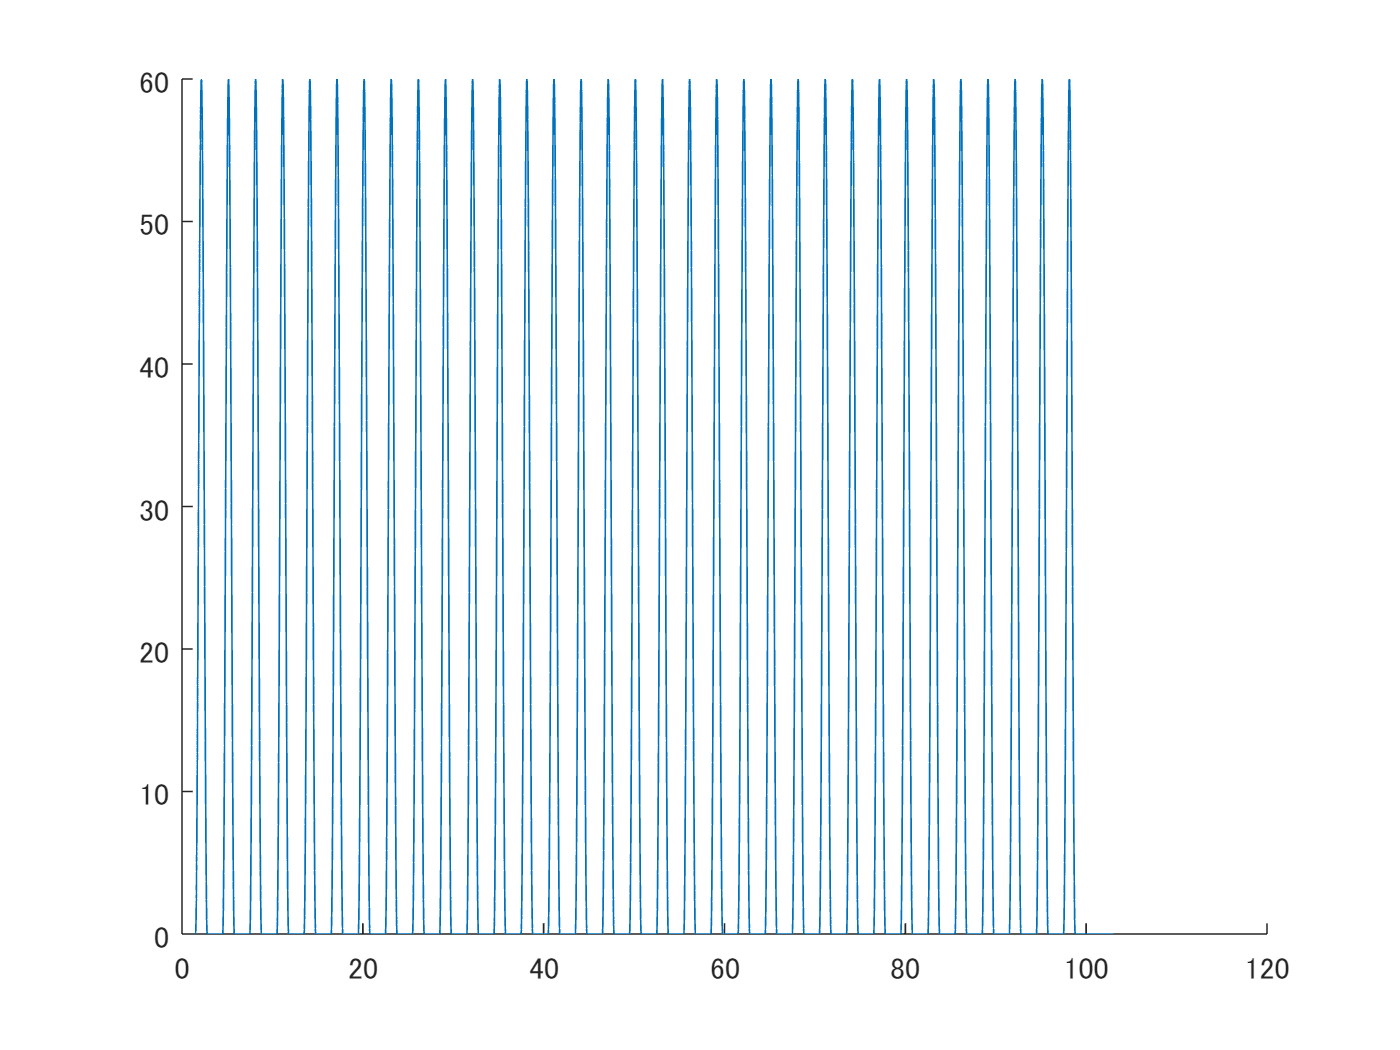

writetable(leftPedal, "leftPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period/2 + waitTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          3       0.64286            60                0      
     3.6429       0.64286             0                0      
          6       0.64286            60                0      
     6.6429       0.64286             0                0      
          9       0.64286            60                0      
     9.6429       0.64286             0                0      
         12       0.64286            60                0      
     12.643       0.64286             0                0      
         15       0.64286            60                0      
     15.643       0.64286             0                0      
         18       0.64286            60                0      
     18.643       0.64286             0                0      
         21       0.64286            60                0      
     21.643       0.64286     

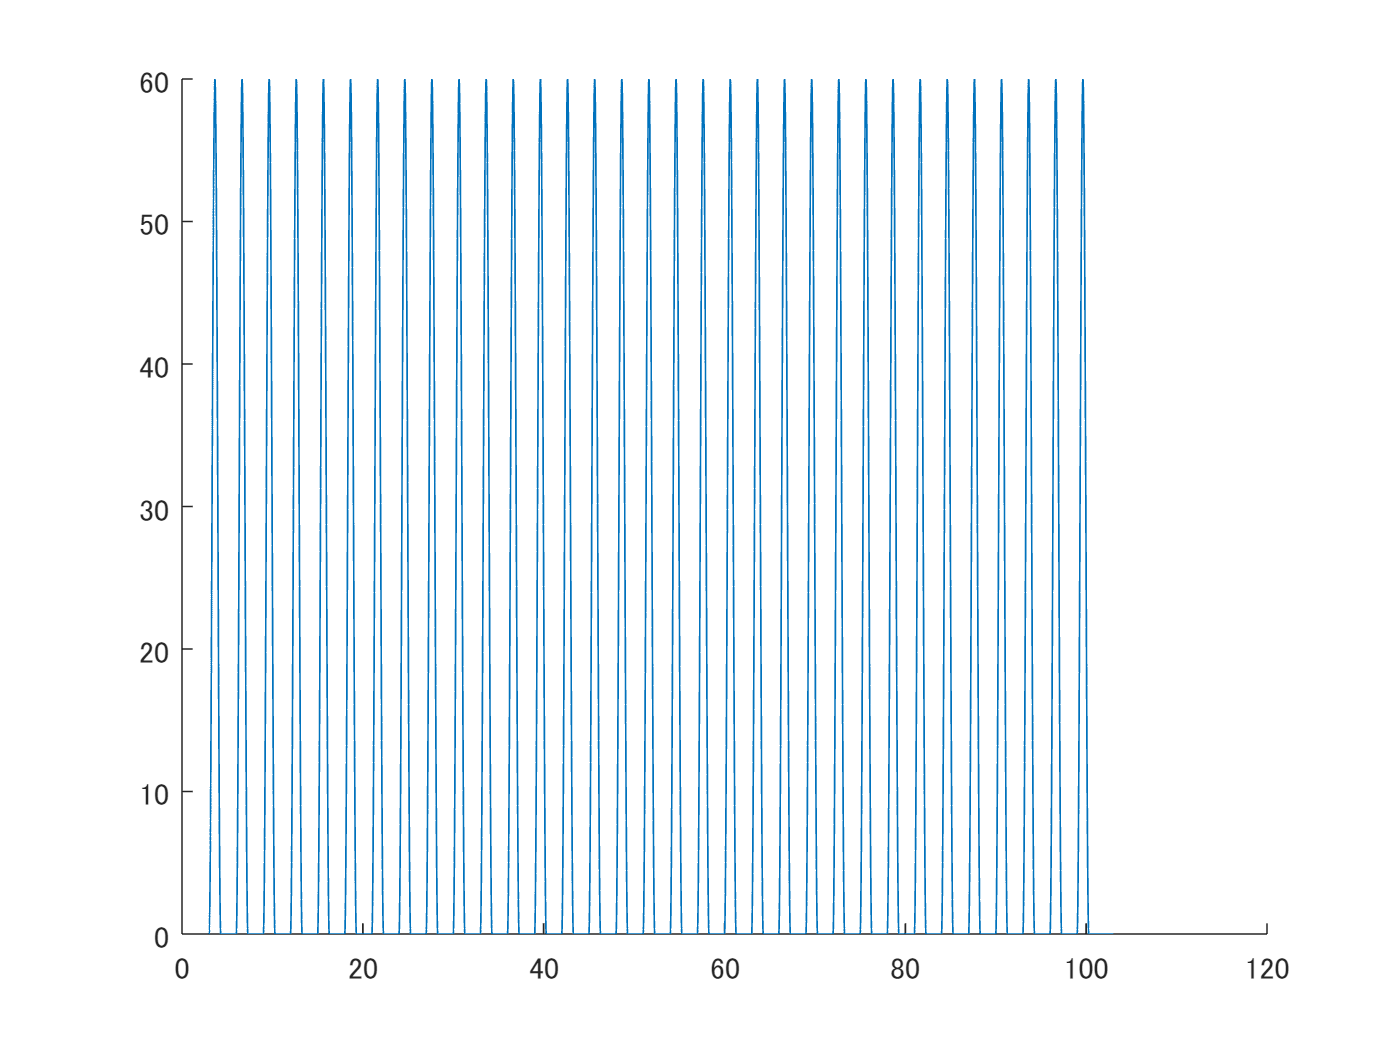

writetable(rightPedal, "rightPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

startClockTime = 0 + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

        1.5       1.2857              50               0      
     2.7857       1.7143            -100               0      
        4.5       1.2857              50               0      
     5.7857       1.7143            -100               0      
        7.5       1.2857              50               0      
     8.7857       1.7143            -100               0      
       10.5       1.2857              50               0      
     11.786       1.7143            -100               0      
       13.5       1.2857              50               0      
     14.786       1.7143            -100               0      
       16.5       1.2857              50               0      
     17.786       1.7143            -100               0      
       19.5       1.2857              50               0      
     20.786       1.7143  

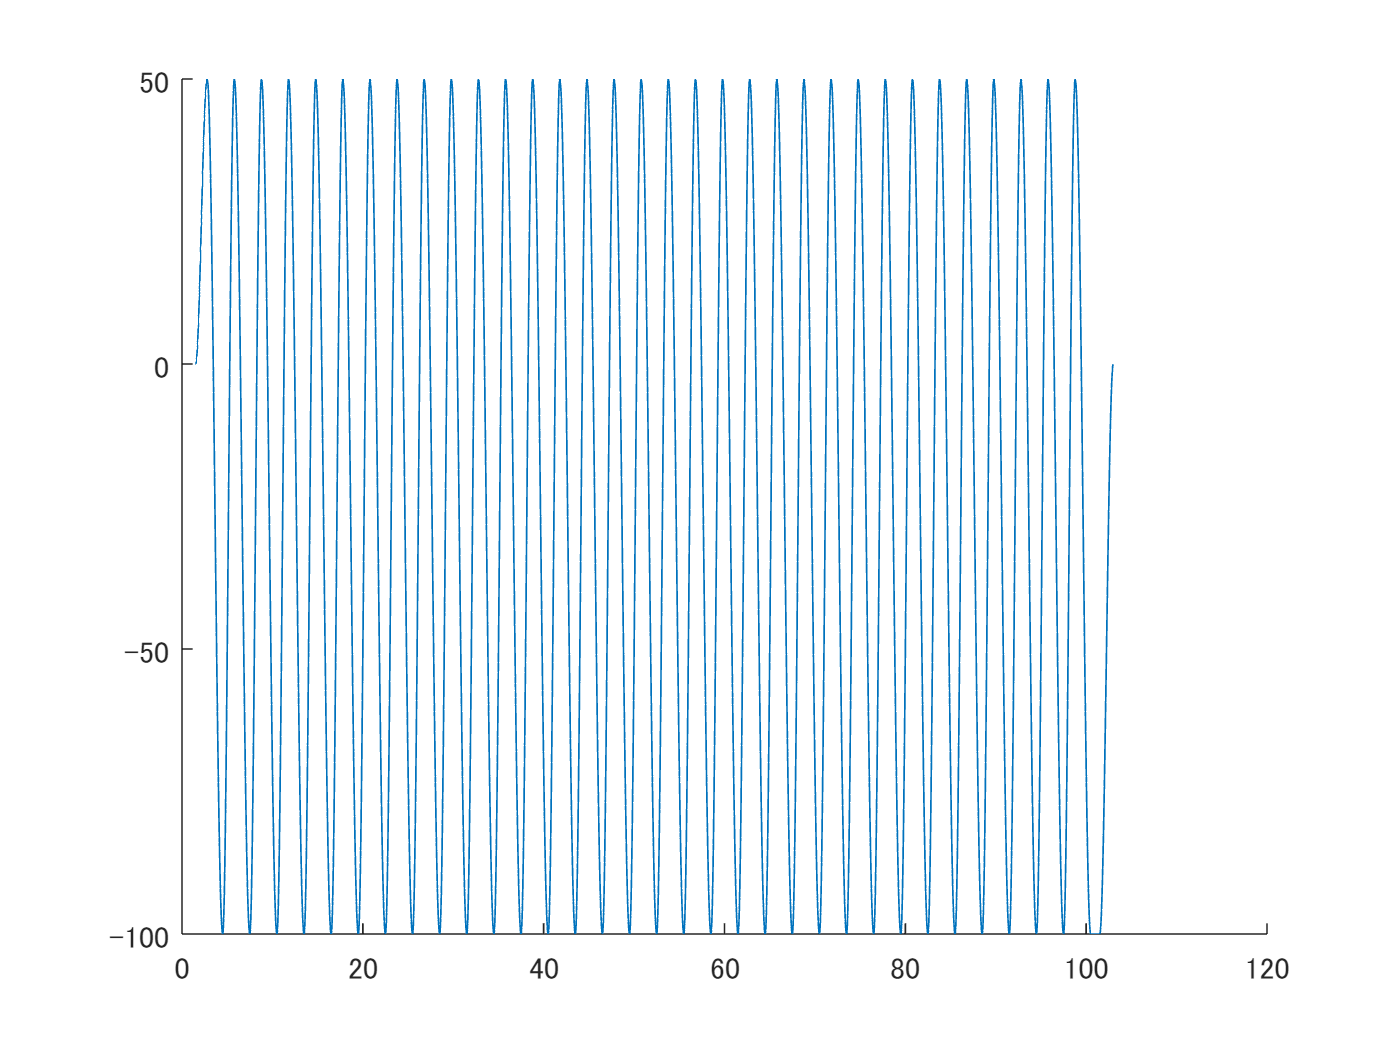

writetable(seatLeftSlider, "seatLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

startClockTime = period/2 + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 65×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          3       1.2857              50               0      
     4.2857       1.7143            -100               0      
          6       1.2857              50               0      
     7.2857       1.7143            -100               0      
          9       1.2857              50               0      
     10.286       1.7143            -100               0      
         12       1.2857              50               0      
     13.286       1.7143            -100               0      
         15       1.2857              50               0      
     16.286       1.7143            -100               0      
         18       1.2857              50               0      
     19.286       1.7143            -100               0      
         21       1.2857              50               0      
     22.286       1.7143 

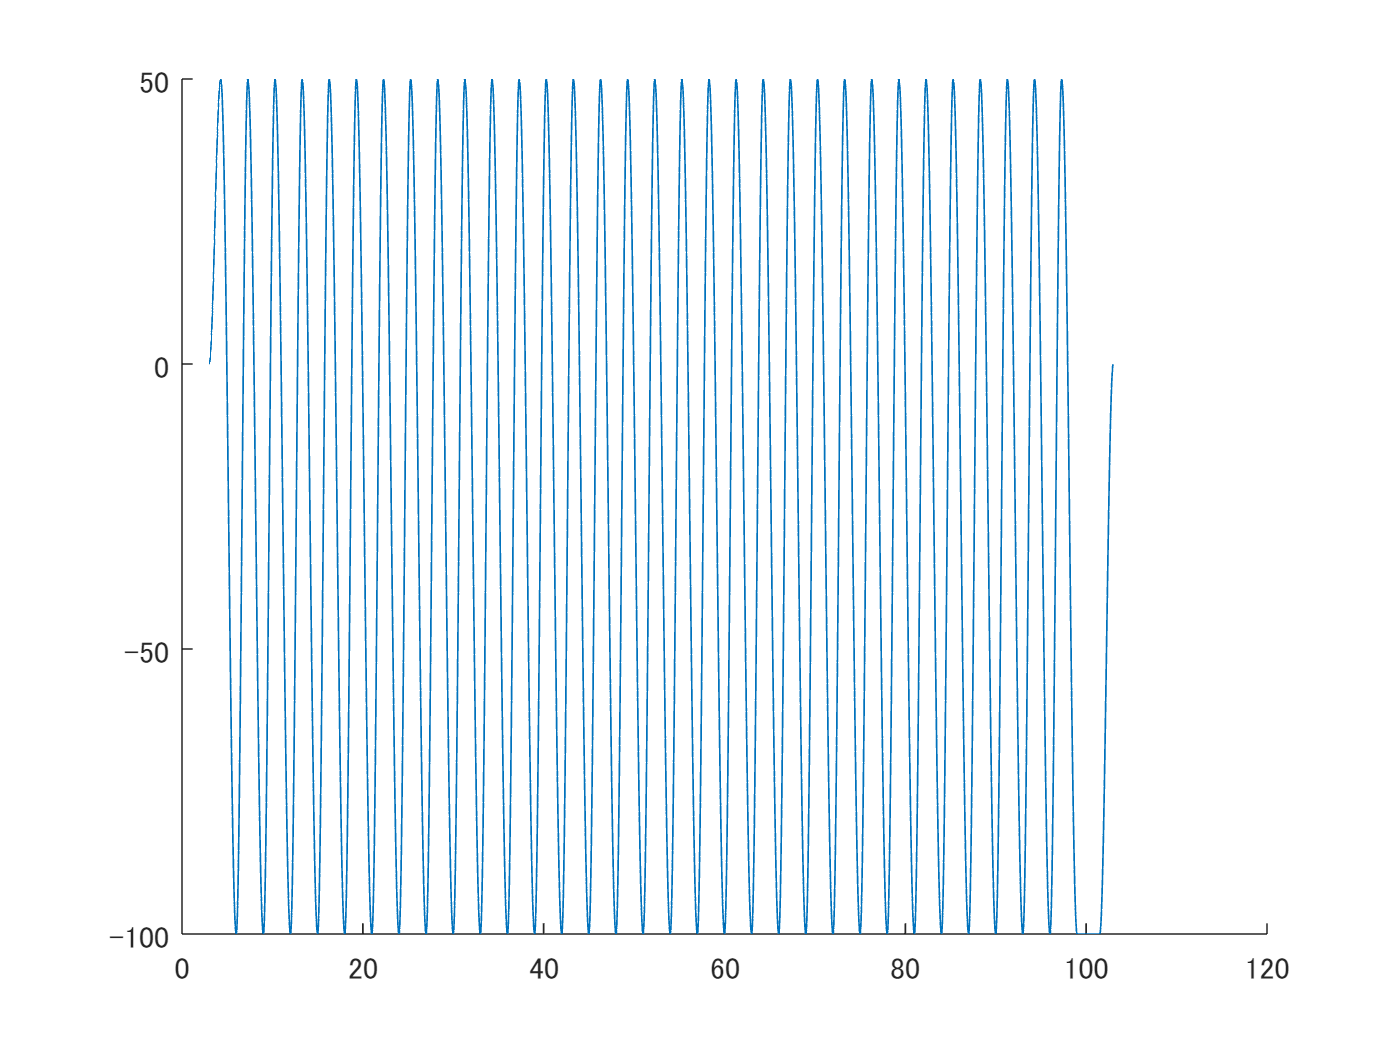

writetable(seatRightSlider, "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックの伸縮　登山

L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime + period/2 + waitTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
useStiffness = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;
useStiffness(end+1) = 0;

stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftExtend = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      2.625       0.64286           180                0      
     3.2679       0.64286             0                1      
      5.625       0.64286           180                0      
     6.2679       0.64286             0                1      
      8.625       0.64286           180                0      
     9.2679       0.64286             0                1      
     11.625       0.64286           180                0      
     12.268       0.64286             0                1      
     14.625       0.64286           180                0      
     15.268       0.64286             0                1      
     17.625       0.64286           180                0      
     18.268       0.64286             0                1      
     20.625       0.64286           180                0      
     21.268       0.64286

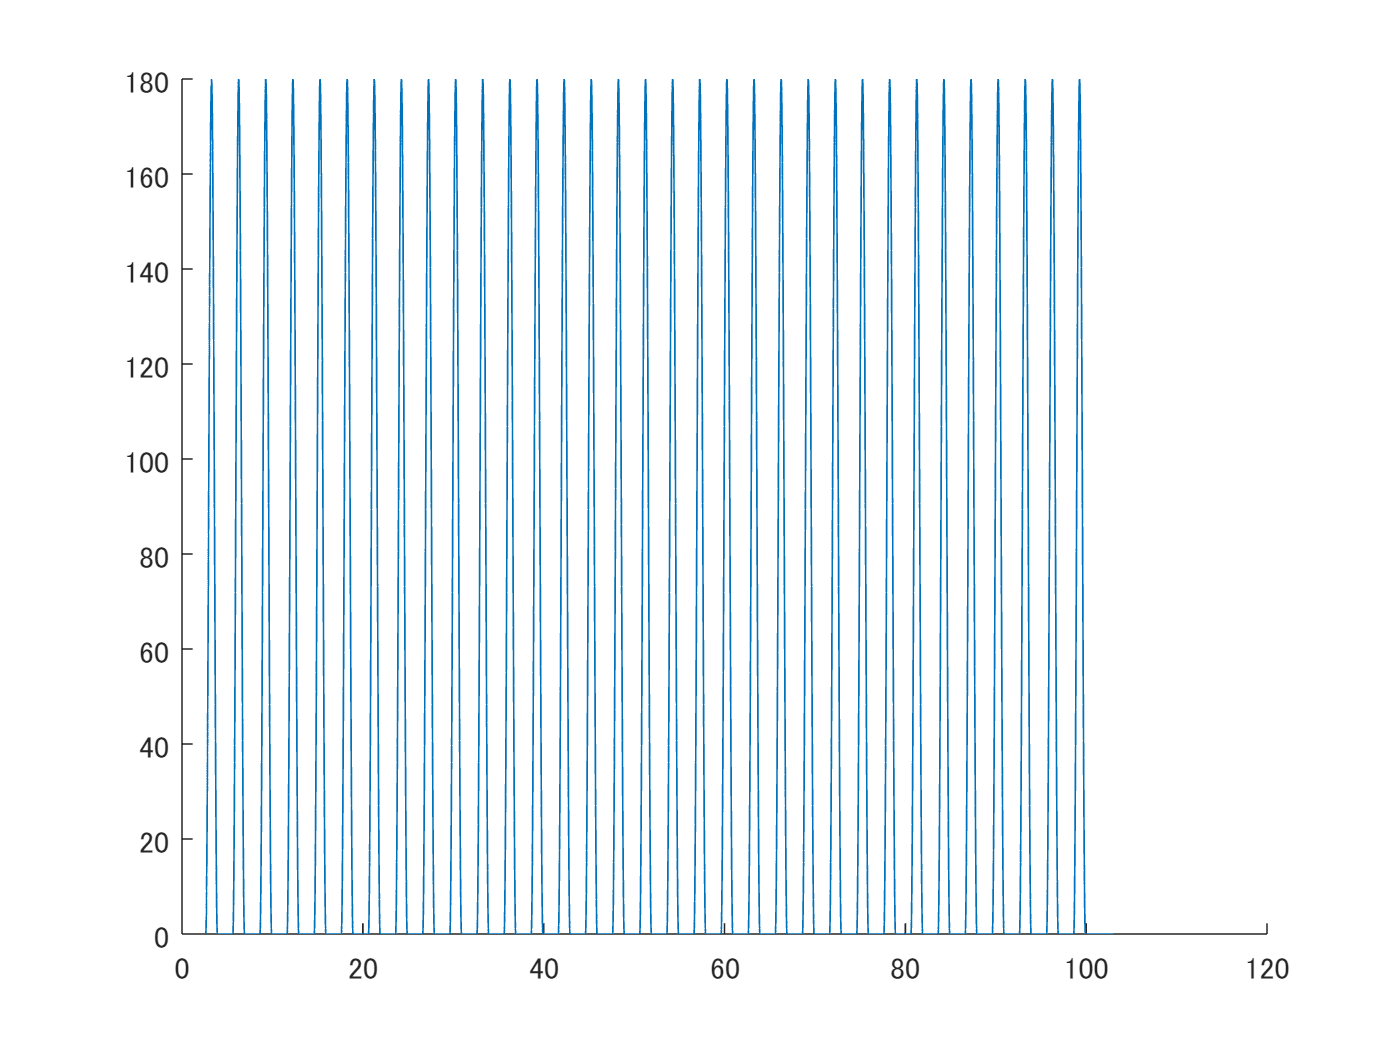

writetable(stockLeftExtend, "stockLeftExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime + waitTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
useStiffness = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;
useStiffness(end+1) = 0;

stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightExtend = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      1.125       0.64286           180                0      
     1.7679       0.64286             0                1      
      4.125       0.64286           180                0      
     4.7679       0.64286             0                1      
      7.125       0.64286           180                0      
     7.7679       0.64286             0                1      
     10.125       0.64286           180                0      
     10.768       0.64286             0                1      
     13.125       0.64286           180                0      
     13.768       0.64286             0                1      
     16.125       0.64286           180                0      
     16.768       0.64286             0                1      
     19.125       0.64286           180                0      
     19.768       0.6428

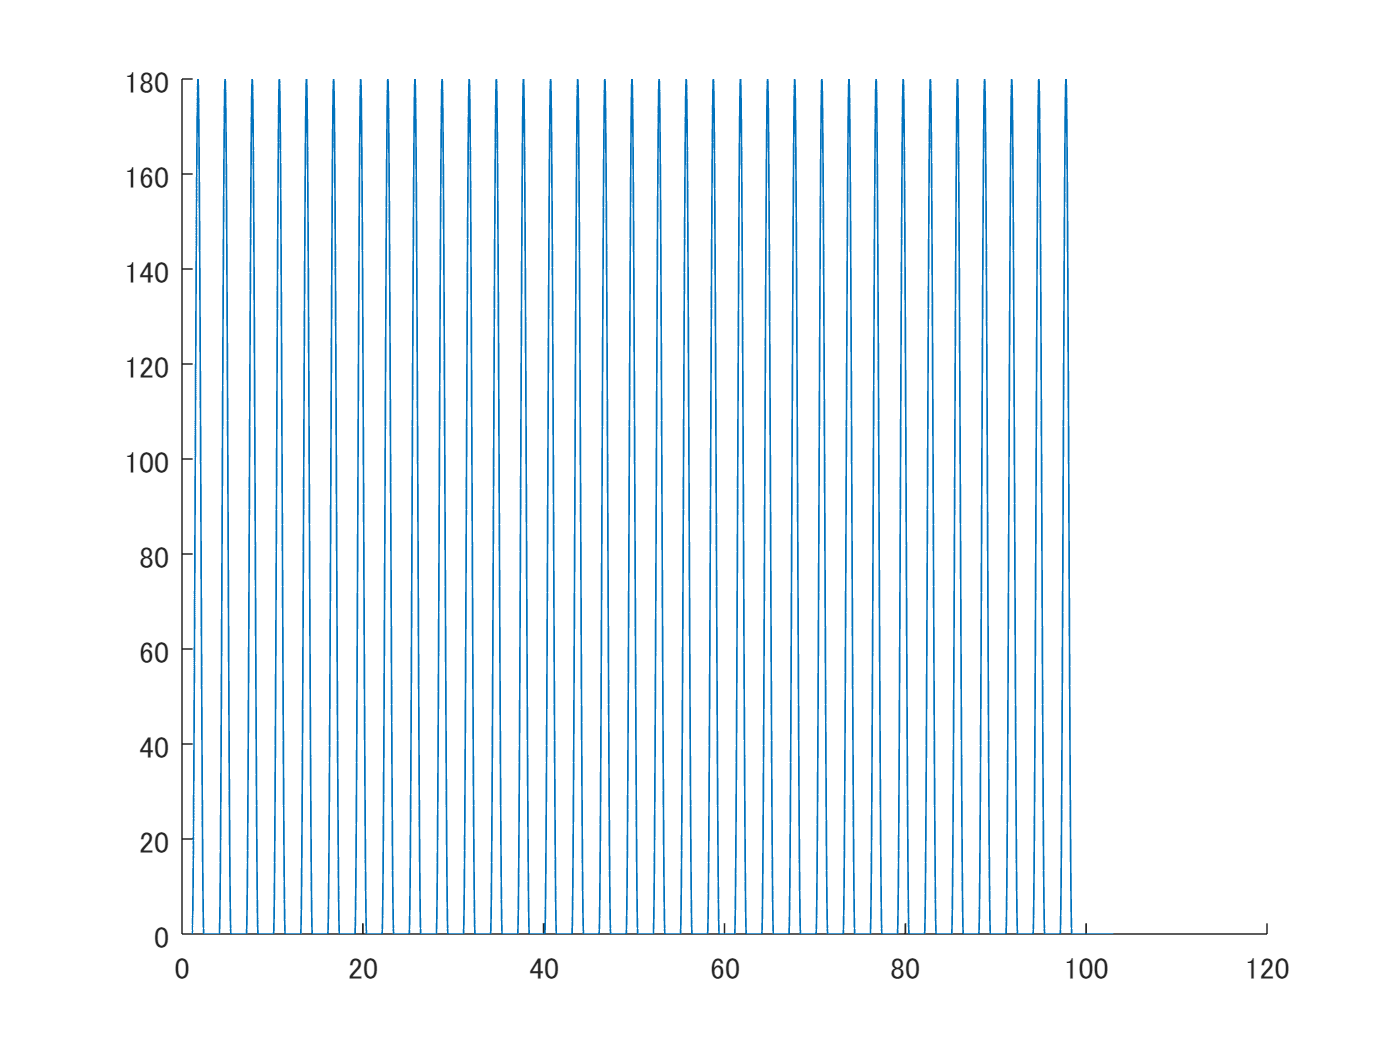

writetable(stockRightExtend, "stockRightExtend.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックのスライダ

startClockTime = stockStartTime + period/2 + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      2.625       1.2857             200               0      
     3.9107       1.7143            -200               0      
      5.625       1.2857             200               0      
     6.9107       1.7143            -200               0      
      8.625       1.2857             200               0      
     9.9107       1.7143            -200               0      
     11.625       1.2857             200               0      
     12.911       1.7143            -200               0      
     14.625       1.2857             200               0      
     15.911       1.7143            -200               0      
     17.625       1.2857             200               0      
     18.911       1.7143            -200               0      
     20.625       1.2857             200               0      
     21.911       1.7143 

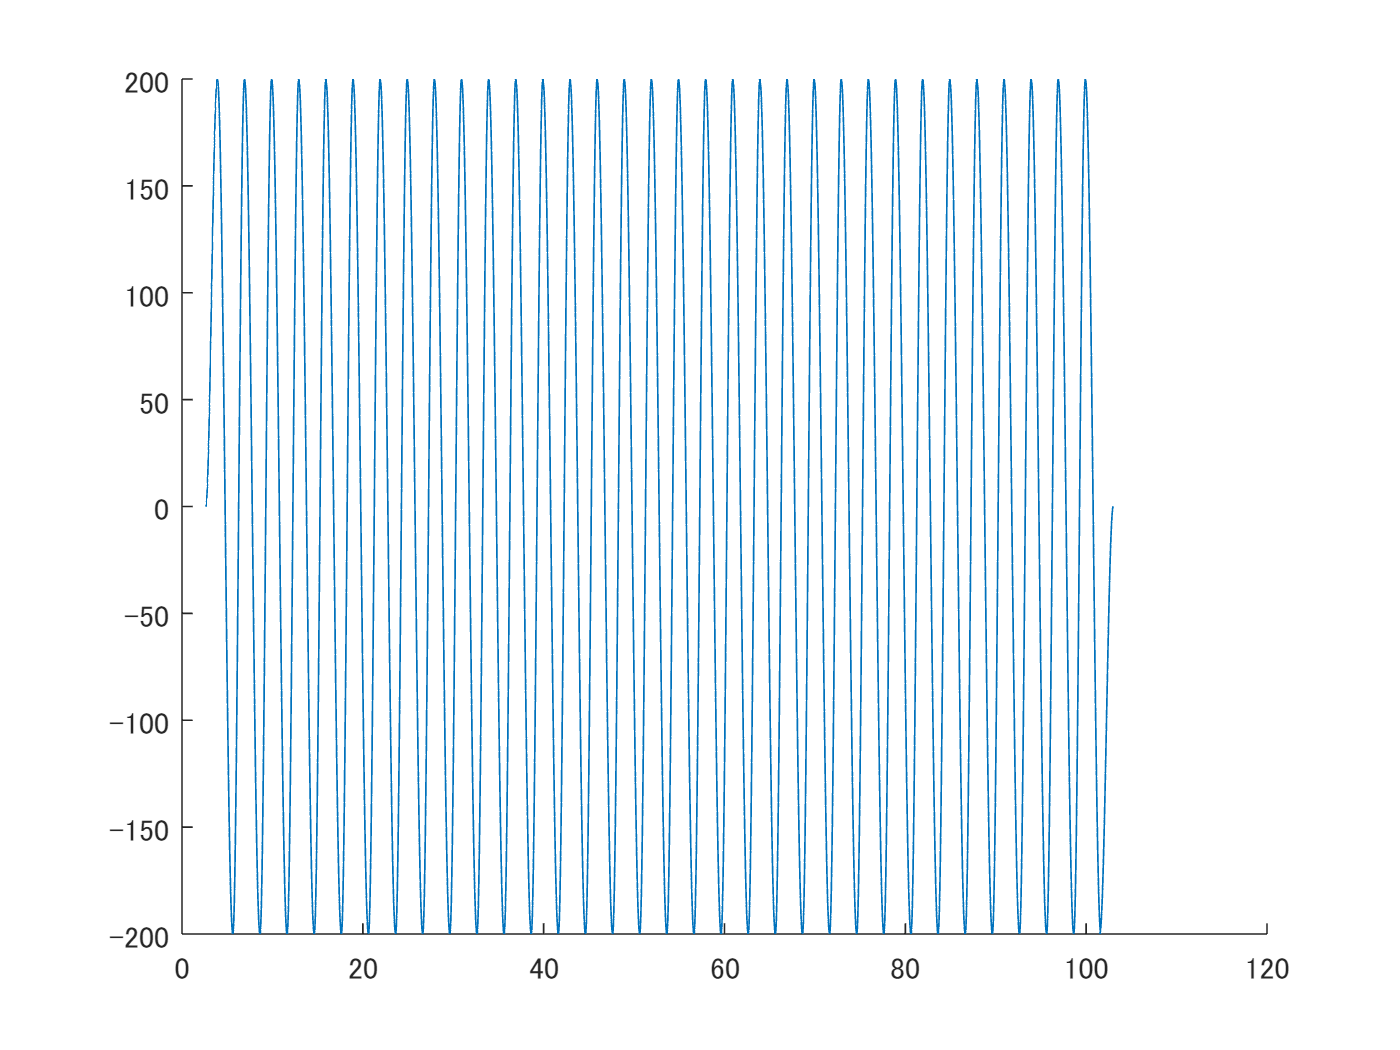

writetable(stockLeftSlider, "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ


L = stockSlideForwardLength; % スライド長 単位 (mm)
startClockTime = stockStartTime + waitTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      1.125       1.2857             200               0      
     2.4107       1.7143            -200               0      
      4.125       1.2857             200               0      
     5.4107       1.7143            -200               0      
      7.125       1.2857             200               0      
     8.4107       1.7143            -200               0      
     10.125       1.2857             200               0      
     11.411       1.7143            -200               0      
     13.125       1.2857             200               0      
     14.411       1.7143            -200               0      
     16.125       1.2857             200               0      
     17.411       1.7143            -200               0      
     19.125       1.2857             200               0      
     20.411       1.7143

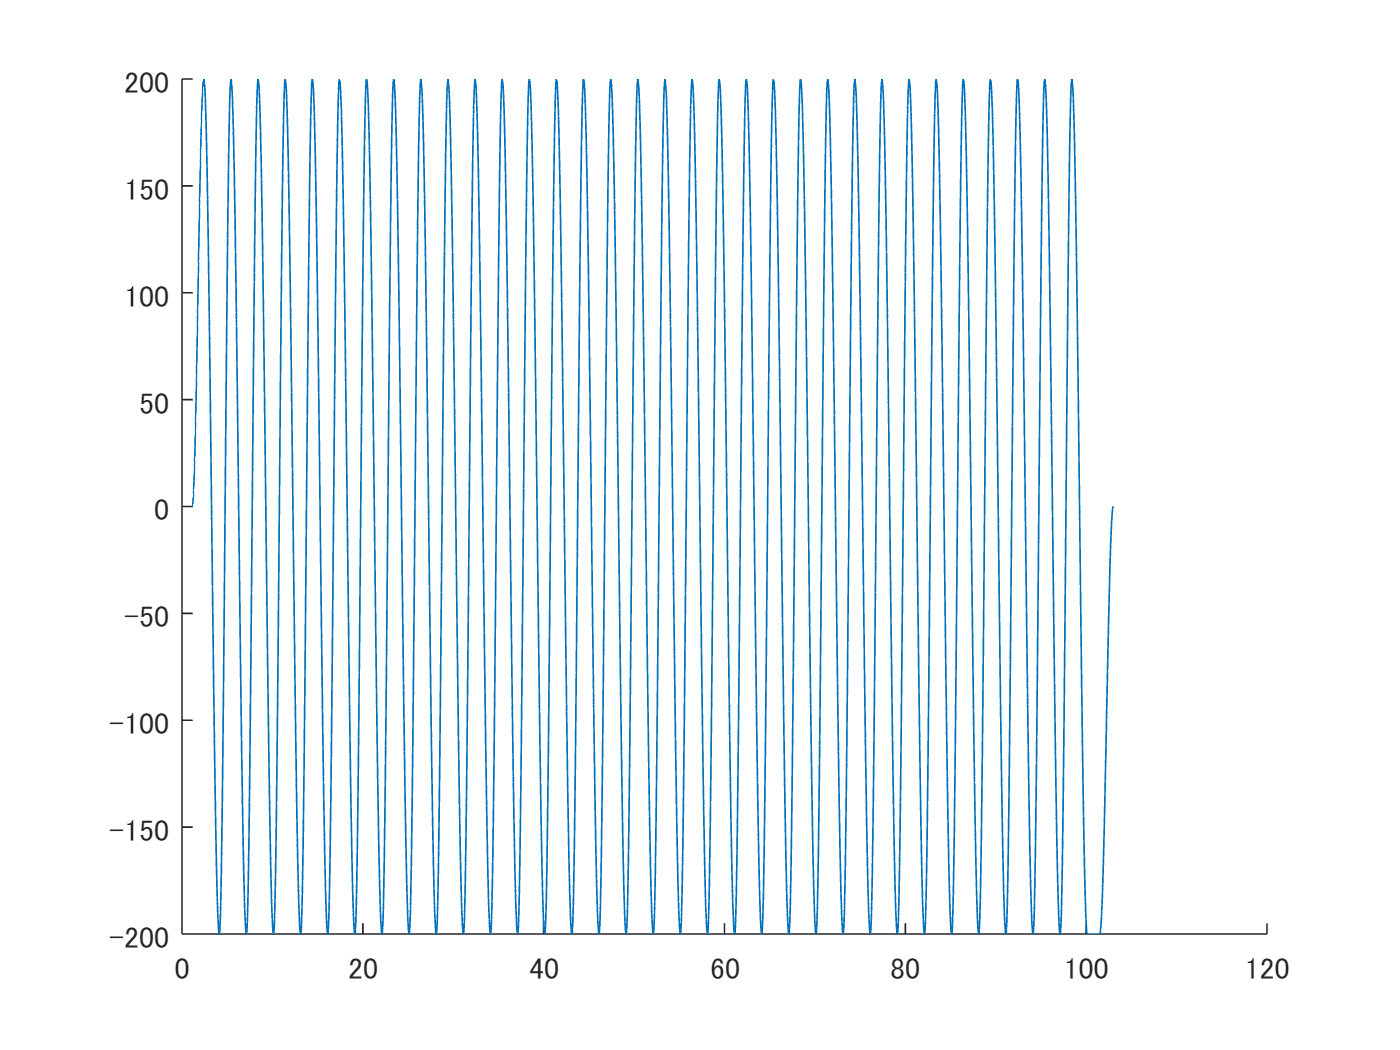

writetable(stockRightSlider, "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeLeftTilt = stockStartTime + period/2 + waitTime - period/10; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% leftTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - leftTiltDeltaTimeF;
leftTiltDelayTimeB = 0;
leftTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = leftTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = leftTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      2.325       1.2857              0                0      
     3.6107       1.7143            -20                0      
      5.325       1.2857              0                0      
     6.6107       1.7143            -20                0      
      8.325       1.2857              0                0      
     9.6107       1.7143            -20                0      
     11.325       1.2857              0                0      
     12.611       1.7143            -20                0      
     14.325       1.2857              0                0      
     15.611       1.7143            -20                0      
     17.325       1.2857              0                0      
     18.611       1.7143            -20                0      
     20.325       1.2857              0                0      
     21.611       1.7143        

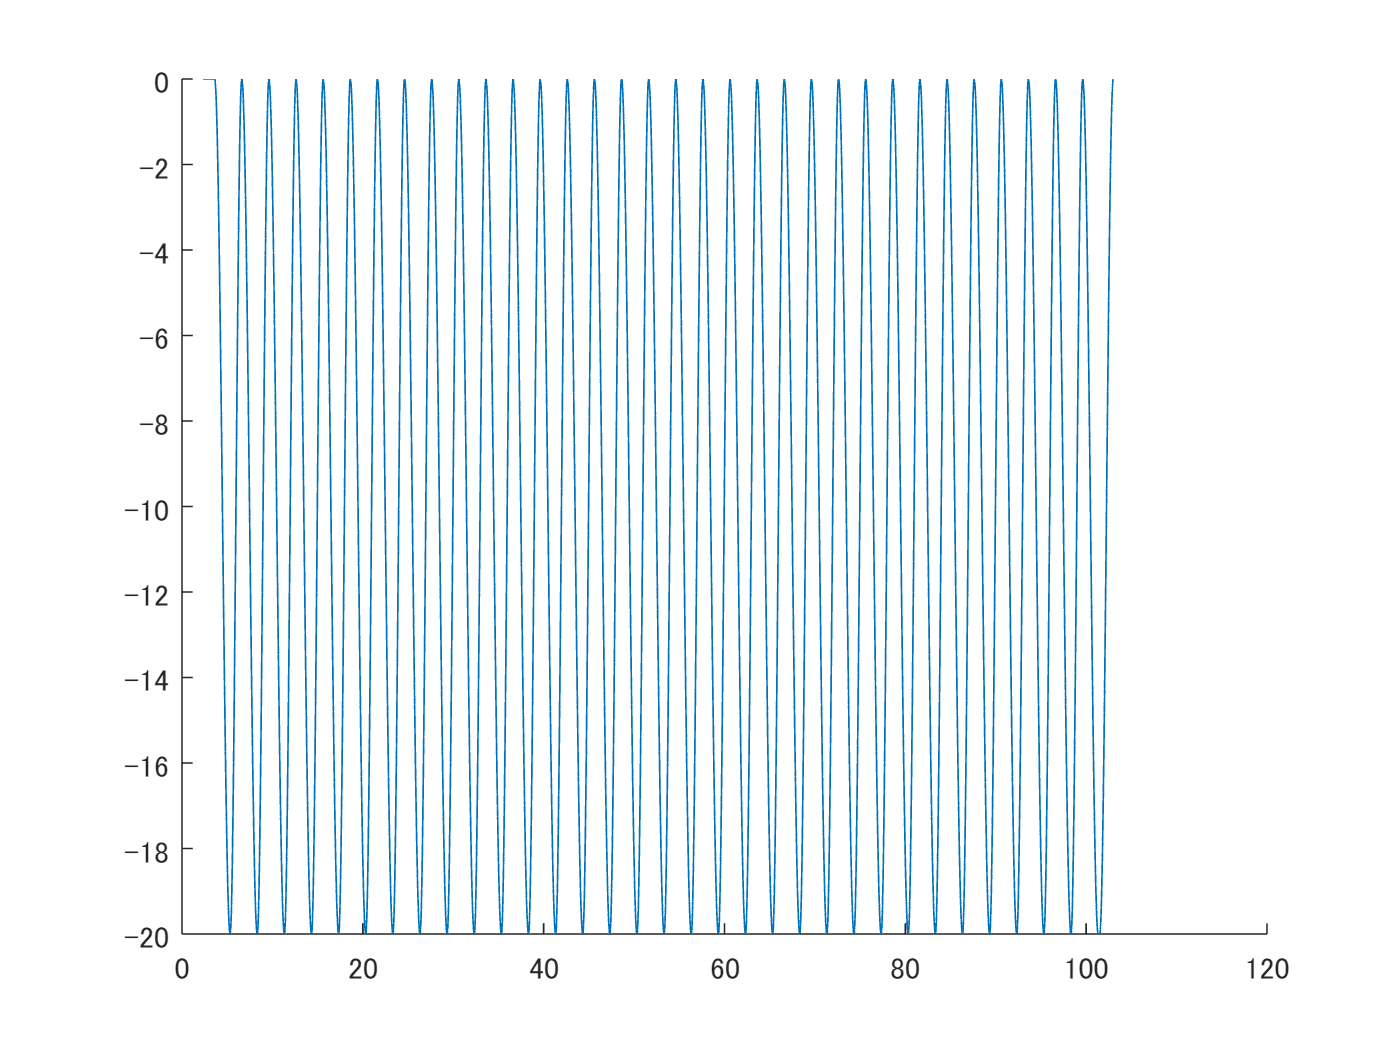

writetable(leftTilt, "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeRightTilt = stockStartTime + waitTime - period/10; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% rightTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - rightTiltDeltaTimeF;
rightTiltDelayTimeB = 0;
rightTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = rightTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = rightTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

      0.825       1.2857              0                0      
     2.1107       1.7143            -20                0      
      3.825       1.2857              0                0      
     5.1107       1.7143            -20                0      
      6.825       1.2857              0                0      
     8.1107       1.7143            -20                0      
      9.825       1.2857              0                0      
     11.111       1.7143            -20                0      
     12.825       1.2857              0                0      
     14.111       1.7143            -20                0      
     15.825       1.2857              0                0      
     17.111       1.7143            -20                0      
     18.825       1.2857              0                0      
     20.111       1.7143       

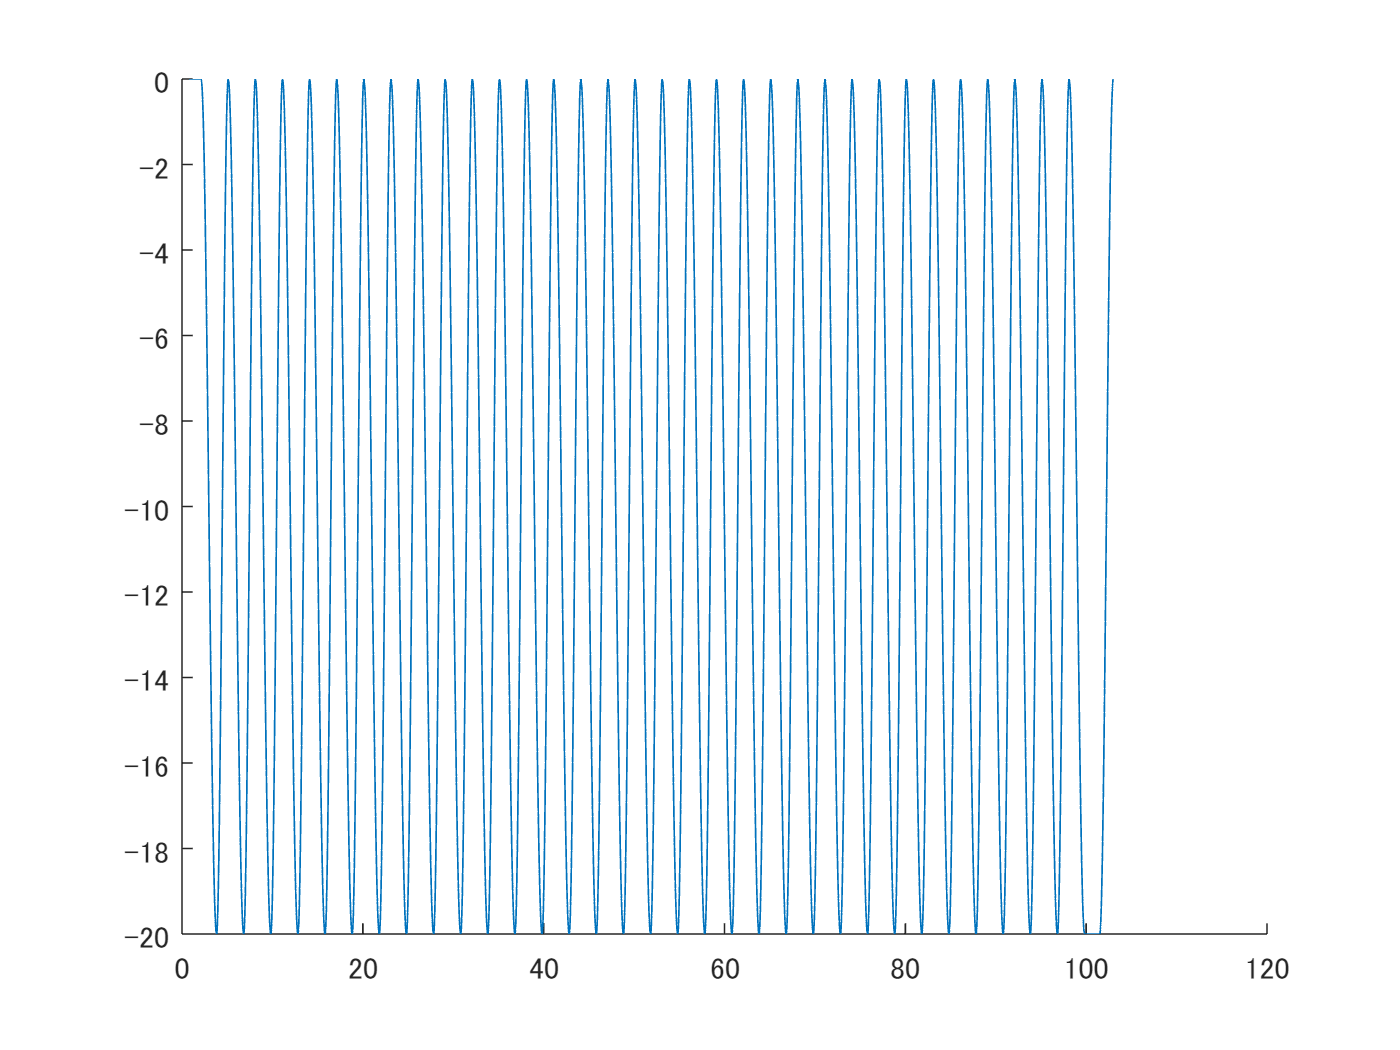

writetable(rightTilt, "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

TiltCSV = table( ...
    period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt, ...
    leftTiltDeltaTimeB, leftTiltDeltaTimeF, rightTiltDeltaTimeB, rightTiltDeltaTimeF, ...
    leftTiltDelayTimeB, leftTiltDelayTimeF, rightTiltDelayTimeB, rightTiltDelayTimeF ...
    )

TiltCSV = 1×15 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt    leftTiltDeltaTimeB    leftTiltDeltaTimeF    rightTiltDeltaTimeB    rightTiltDeltaTimeF    leftTiltDelayTimeB    leftTiltDelayTimeF    rightTiltDelayTimeB    rightTiltDelayTimeF
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________    __________________    __________________    ___________________    ___________________    __________________    __________________    ___________________    ___________________

      3              0                -20                   3                       4                     2.325                      0.825                   1.2857                1.7143                1.2857                 1.7143                   0                     0                      0                      0    

writetable(TiltCSV, 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end
